# 第2章 图像增强

## 例2-4 灰度线性变换

请编写MATLAB程序，实现对pout图像进行灰度线性变换，将图像灰度值从$0.3 \times 255 \sim 0.7 \times 255
 $ 之间映射到$0 \sim 255$之间

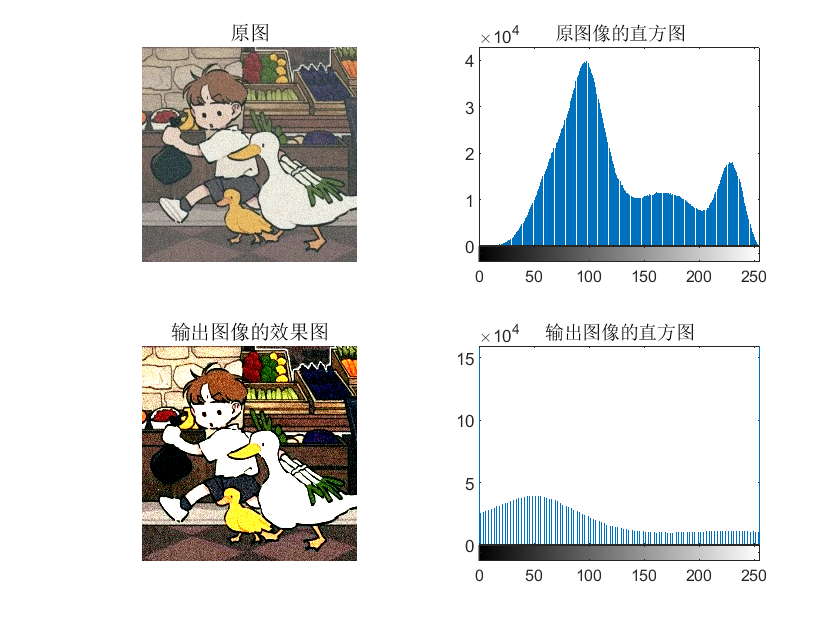

I=imread('pappers.png');%%读取图像
figure();
subplot(2,2,1);
imshow(I);%%显示原图
title('原图');
subplot(2,2,2);
imhist(I);
title('原图像的直方图');
J1=imadjust(I,[0.3,0.7],[]);
subplot(2,2,3);
imshow(J1);
title('输出图像的效果图');
subplot(2,2,4);
imhist(J1);
title('输出图像的直方图');

## 例2-5 通过直方图均衡化对图像增强

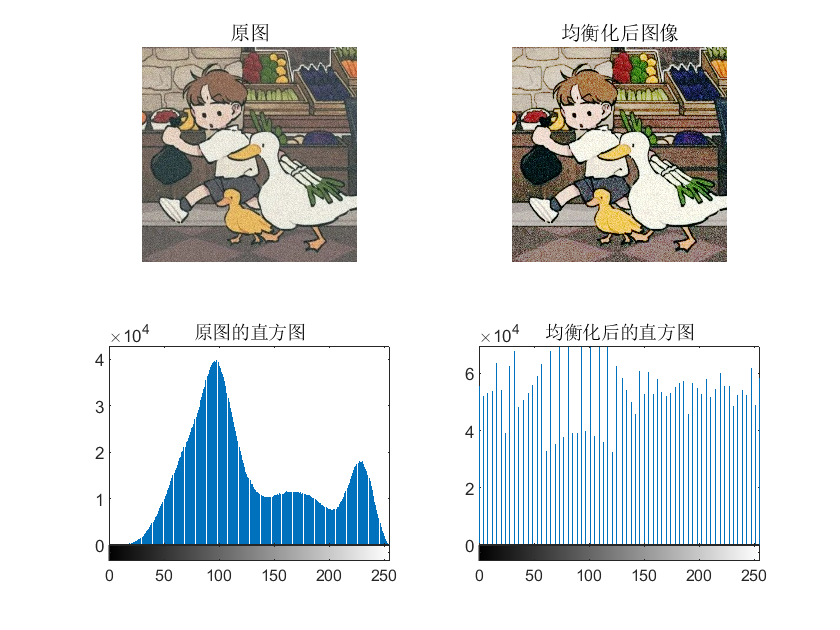

A=imread('pappers.png');
I=histeq(A);
figure();
subplot(2,2,1),imshow(A);
title('原图');
subplot(2,2,2),imshow(I);
title('均衡化后图像');
subplot(2,2,3),imhist(A);
title('原图的直方图');
subplot(2,2,4),imhist(I);
title('均衡化后的直方图')

## 例2-6 平滑处理

分别采用3种模板对含噪图像进行平滑处理

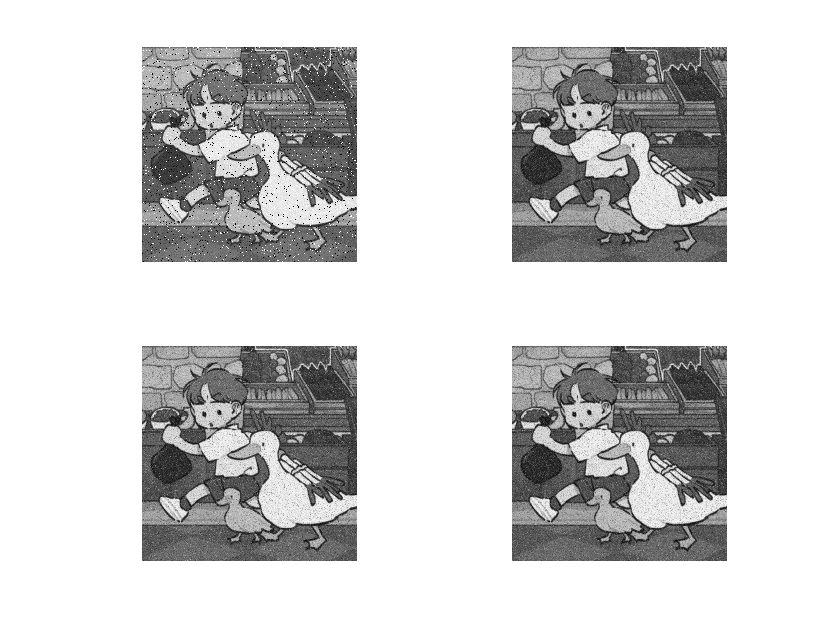

I1=imread('pappers.png');%%彩图
I1=im2gray(I1);%%彩图转化成灰图
I=imnoise(I1,'salt & pepper');
h1=[0.1 0.1 0.1;0.1 0.2 0.1;0.1 0.1 0.1];
h2=1/16.*[1 2 1;2 4 2;1 2 1];
h3=1/8.*[1 1 1;1 0 1;1 1 1];
I2=filter2(h1,I);
I3=filter2(h2,I);
I4=filter2(h3,I);
figure();
subplot(2,2,1),imshow(I);
subplot(2,2,2),imshow(I2,[]);
subplot(2,2,3),imshow(I3,[]);
subplot(2,2,4),imshow(I4,[]);

## 例2-7：同态滤波

对图像进行同态滤波

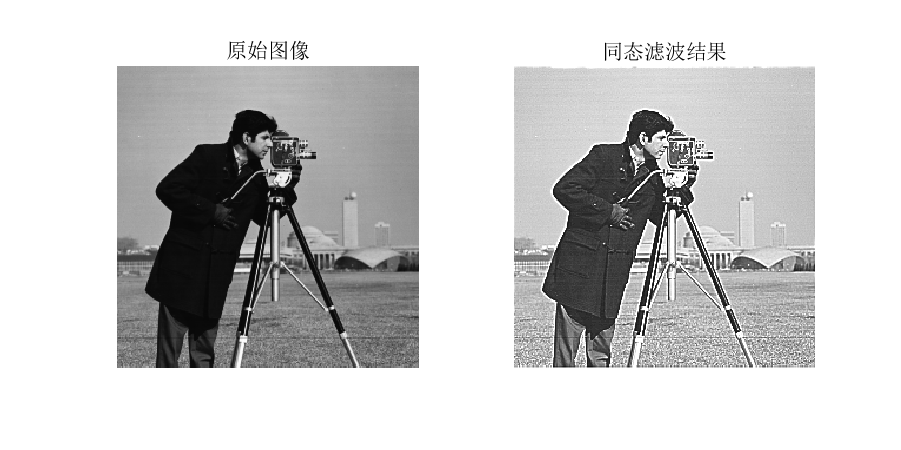

I=imread('cameraman.tif');
figure('Position',[0,0,600,300]);
subplot(1,2,1);
imshow(I);
title('原始图像');
I=im2double(I);
lni=log(I+0.000001);
Fi=fftshift(fft2(lni));
[M,N]=size(Fi);
xo=floor(M/2);
yo=floor(N/2);
Hh=2;
Hl=0.5;
c=1.50;
D0=80;
h=zeros(M,N);
for i=1:M
    for j=1:N
        D=(i-xo)^2+(j-yo)^2;
        h(i,j)=(Hh-Hl)*(1-exp(-c*(D/D0^2)))+Hl;
    end
end
Gi=h.*Fi;
flno=ifftshift(Gi);
go=real(ifft2(flno));

go=exp(go);
gxy=im2uint8(go);
subplot(1,2,2);imshow(gxy);title('同态滤波结果');

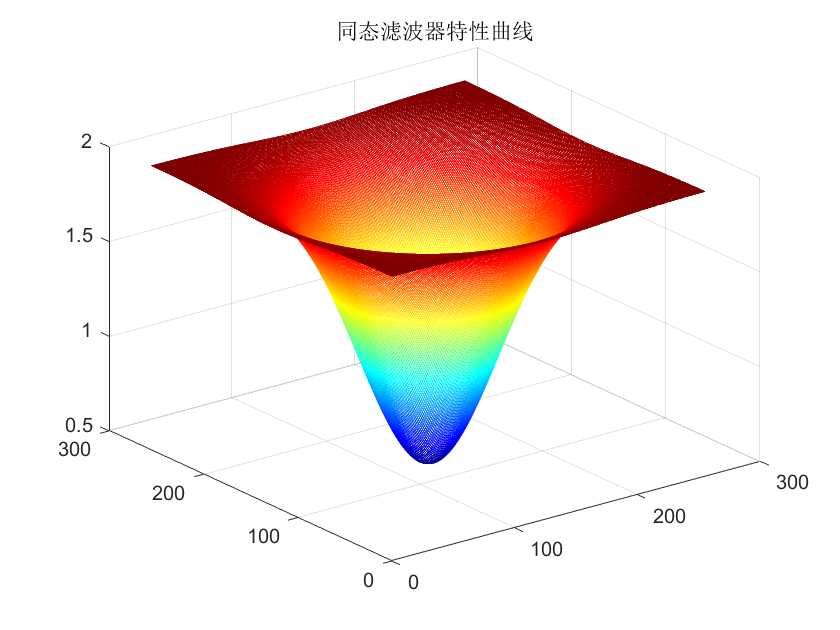

figure();
mesh(h);
colormap(jet);
title('同态滤波器特性曲线');